# Constant speed, curved path

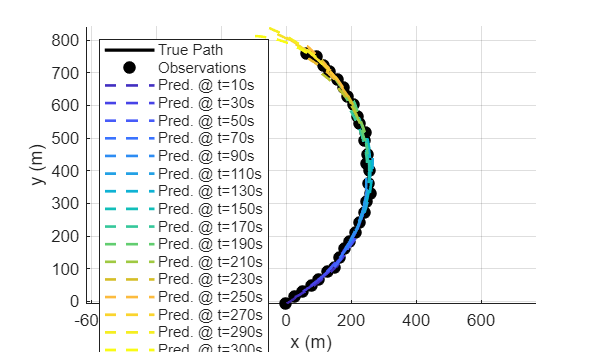

%% Sparse updates with NON-straight motion (Constant-Speed Coordinated-Turn)
% Truth: constant speed v, constant turn-rate omega (circular/arc path)
% Measurements: [x, y, theta]
% Filter: EKF on [x; y; v; psi; omega]; h(x) = [x; y; psi]
% At each update, predict ahead and compare to truth

clear; clc; close all;

%% Scenario Parameters 
Tf          = 300;        % total duration [s]
dt_truth    = 1;        % truth propagation step [s]
dt_filter   = 1;        % filter propagation step [s]
T_meas      = 10;       % measurement interval [s]
T_pred      = 60;       % prediction horizon [s]

% Ground truth motion (constant speed, constant turn-rate)
x0_true     = 0;           % m
y0_true     = 0;           % m
v_true      = 3.09;         % m/s
psi0_true   = deg2rad(25); % rad initial heading
omega_true  = deg2rad(4)/10; % rad/s

% Measurement noise (AIS-like)
sigma_xy    = 3;          % m
sigma_th    = deg2rad(2); % rad

% Process noise (model errors): small drift on psi and omega
sigma_v     = 0.02;          % m/s   (speed nearly constant)
sigma_psi   = deg2rad(0.2);  % rad
sigma_omega = deg2rad(0.05); % rad/s

rng(2); % reproducible

wrapAng = @(a) atan2(sin(a), cos(a)); % robust wrap to [-pi,pi]

%% Coordinated-Turn Propagation
% State: x = [x; y; v; psi; omega]
f_ct = @(x, dt) propagate_ct(x, dt);
% Numerical Jacobian for EKF (w.r.t. state)
F_num = @(x, dt) numJacobian(@(xx) f_ct(xx, dt), x);

% Measurement model: z = [x; y; psi] + noise
h     = @(x) [x(1); x(2); wrapAng(x(4))];
H     = @(x) [1 0 0 0 0;
              0 1 0 0 0;
              0 0 0 1 0];

R = diag([sigma_xy^2, sigma_xy^2, sigma_th^2]);

% Discrete process noise (tuned): Q ~ diag for [x,y,v,psi,omega]
Q_from_dt = @(dt) diag([ ...
    (0.5*v_true*dt)^2, ...  % x (position grows with v*dt)
    (0.5*v_true*dt)^2, ...  % y
    (sigma_v*sqrt(dt))^2, ...
    (sigma_psi*sqrt(dt))^2, ...
    (sigma_omega*sqrt(dt))^2 ]);

%% Truth Trajectory
t_truth = 0:dt_truth:Tf;
N_truth = numel(t_truth);
X_true  = zeros(5, N_truth);       % [x;y;v;psi;omega]
X_true(:,1) = [x0_true; y0_true; v_true; psi0_true; omega_true];

for k = 2:N_truth
    X_true(:,k) = f_ct(X_true(:,k-1), dt_truth); % perfect CT truth
end

%% Measurements
t_meas = 0:T_meas:Tf;
N_meas = numel(t_meas);
z_meas = zeros(3, N_meas); % [x;y;theta]

idx_meas_truth = round(t_meas/dt_truth) + 1;
for i = 1:N_meas
    kk = idx_meas_truth(i);
    z_true = h(X_true(:,kk));
    z_meas(:,i) = [ z_true(1) + sigma_xy*randn;
                    z_true(2) + sigma_xy*randn;
                    wrapAng(z_true(3) + sigma_th*randn) ];
end

%% EKF Initialisation (boot)
% Use first THREE measurements to estimate v and omega robustly
if N_meas < 3
    error('Need at least three measurements for curved-motion initialisation.');
end

% Positions and headings
p1 = z_meas(1:2,1); th1 = z_meas(3,1);
p2 = z_meas(1:2,2); th2 = z_meas(3,2);
p3 = z_meas(1:2,3); th3 = z_meas(3,3);

dt12 = t_meas(2) - t_meas(1);
dt23 = t_meas(3) - t_meas(2);

% Speed from p1->p2 (coarse)
v_est = norm(p2 - p1) / max(dt12,1e-6);
% Heading from 2nd measurement (less noisy than finite differences on tiny moves)
psi_init = th2;

% Turn-rate from heading change (2nd to 3rd)
omega_est = wrapAng(th3 - th2) / max(dt23,1e-6);

xhat = [p2(1); p2(2); max(v_est, 0.1); psi_init; omega_est];

Phat = diag([ ...
    (sigma_xy*4)^2, (sigma_xy*4)^2, ...  % position
    (max(v_est,0.5))^2, ...              % speed
    (deg2rad(10))^2, ...                  % heading
    (deg2rad(2)/max(dt23,1))^2 ]);        % turn-rate

%% Run EKF & Predict
t_filter = 0:dt_filter:Tf;
N_filt   = numel(t_filter);
X_filt   = nan(5, N_filt);

predictions = cell(N_meas,1);
pred_truth  = cell(N_meas,1);
pred_stats  = []; % [t_update, RMSE_pos, MAE_pos, v_est, v_err, psi_est, psi_err_deg, omega_est, omega_err_deg_s]

meas_ptr = 1;

for k = 1:N_filt
    t_now = t_filter(k);

    % 1) Predict step
    Fk  = F_num(xhat, dt_filter);
    Qk  = Q_from_dt(dt_filter);
    xhat = f_ct(xhat, dt_filter);
    Phat = Fk*Phat*Fk' + Qk;

    X_filt(:,k) = xhat;

    % 2) Update on measurement times
    if meas_ptr <= N_meas && abs(t_now - t_meas(meas_ptr)) < 1e-9
        z   = z_meas(:,meas_ptr);
        zhat = h(xhat);

        innov = z - zhat;
        innov(3) = wrapAng(innov(3));

        Hk = H(xhat);
        S  = Hk*Phat*Hk' + R;
        K  = Phat*Hk'/S;

        xhat = xhat + K*innov;
        Phat = (eye(5) - K*Hk)*Phat;

        % 3) Roll out future prediction T_pred ahead with CT model
        Np = round(T_pred/dt_filter);
        future = zeros(5, Np+1); future(:,1) = xhat;
        xpr = xhat; Ppr = Phat;
        for j = 2:Np+1
            Fp  = F_num(xpr, dt_filter);
            Qp  = Q_from_dt(dt_filter);
            xpr = f_ct(xpr, dt_filter);
            Ppr = Fp*Ppr*Fp' + Qp;
            future(:,j) = xpr;
        end

        % Get corresponding truth segment
        t0 = t_now; tfh = min(t_now + T_pred, Tf);
        idx0 = round(t0/dt_truth)+1;
        idxf = min(round(tfh/dt_truth)+1, N_truth);
        truth_seg = X_true(:, idx0:idxf);

        predictions{meas_ptr} = struct('t0',t0,'dt',dt_filter,'states',future);
        pred_truth{meas_ptr}  = struct('states',truth_seg);

        % Metrics over horizon (position error)
        np = min(size(future,2), size(truth_seg,2));
        pred_xy = future(1:2,1:np);
        true_xy = truth_seg(1:2,1:np);
        pos_err = vecnorm(pred_xy - true_xy, 2, 1);
        rmse_pos = sqrt(mean(pos_err.^2));
        mae_pos  = mean(abs(pos_err));

        v_est_k   = xhat(3);
        psi_est_k = xhat(4);
        omg_est_k = xhat(5);

        v_err     = v_est_k - v_true;
        psi_err   = rad2deg(wrapAng(psi_est_k - X_true(4, idx0)));
        omg_err   = rad2deg(omg_est_k - omega_true); 
        omg_err   = omg_err; 

        pred_stats = [pred_stats; t_now, rmse_pos, mae_pos, ...
                      v_est_k, v_err, psi_est_k, psi_err, omg_est_k, omg_err]; %#ok<AGROW>

        meas_ptr = meas_ptr + 1;
    end
end

%% Plots
% Plot 1
figure('Color','w','Position',[100 100 1200 700]);
hold on; grid on; axis equal;
xlabel('x (m)'); ylabel('y (m)');

% Truth path and observations
plot(X_true(1,:), X_true(2,:), 'k-', 'LineWidth', 2, 'DisplayName', 'True Path');
plot(z_meas(1,:), z_meas(2,:), 'ko', 'MarkerSize', 7, ...
     'MarkerFaceColor','k', 'DisplayName', 'Observations');

% Coloured horizons (label every 2nd, and always the last, to avoid legend spam)
n_updates = numel(predictions);
draw_idx  = 1:n_updates;                   % draw all
colors    = parula(numel(draw_idx));       % (parula/turbo/lines)

for ii = 1:numel(draw_idx)
    i = draw_idx(ii);
    S = predictions{i};
    if isempty(S), continue; end
    xy = S.states(1:2,:);
    if mod(i,2)==0 || i==draw_idx(end)
        lbl = sprintf('Pred. @ t=%.0fs', round(t_meas(i)));
        vis = 'on';
    else
        lbl = '';
        vis = 'off';
    end
    plot(xy(1,:), xy(2,:), '--', 'Color', colors(ii,:), ...
         'LineWidth', 1.6, 'DisplayName', lbl, 'HandleVisibility', vis);
end

legend('Location','northwest');

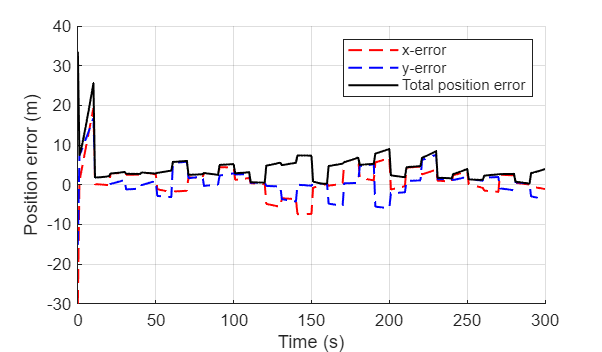


% Plot 2
%% Compute and Plot Position Error
% Interpolate EKF filtered estimates onto truth time grid for fair comparison
valid_idx = find(all(~isnan(X_filt(1:2,:)),1));
t_valid   = t_filter(valid_idx);
x_filt_i  = interp1(t_valid, X_filt(1,valid_idx), t_truth, 'linear', 'extrap');
y_filt_i  = interp1(t_valid, X_filt(2,valid_idx), t_truth, 'linear', 'extrap');

% Compute position error components
x_err = X_true(1,:) - x_filt_i;
y_err = X_true(2,:) - y_filt_i;
pos_err_total = sqrt(x_err.^2 + y_err.^2);

% Plot errors
figure('Color','w','Position',[100 100 1200 700]); hold on; grid on;
plot(t_truth, x_err, 'r--', 'LineWidth', 1.2);
plot(t_truth, y_err, 'b--', 'LineWidth', 1.2);
plot(t_truth, pos_err_total, 'k', 'LineWidth', 1.2);
xlabel('Time (s)');
ylabel('Position error (m)');
legend({'x-error','y-error','Total position error'}, 'Location','northeast');

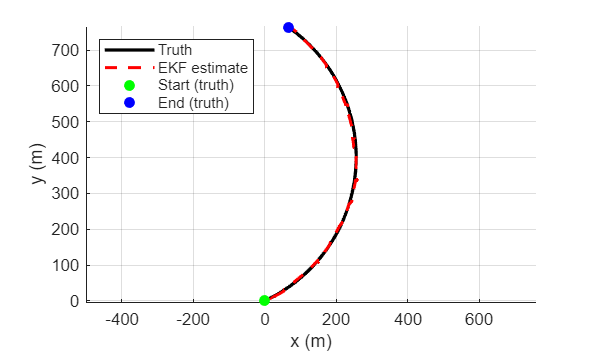


% Plot 3
% Trajectory comparison (x–y): Truth vs EKF estimates
figure('Color','w','Position',[100 100 1200 700]); clf; hold on; grid on; axis equal;
xlabel('x (m)'); ylabel('y (m)');

% True trajectory (from X_true built earlier)
plot(X_true(1,:), X_true(2,:), 'k-', 'LineWidth', 2, 'DisplayName','Truth');

% EKF trajectory (from X_filt built during filtering)
% Keep only valid (non-NaN) samples
valid_idx = find(all(~isnan(X_filt(1:2,:)),1));
x_est = X_filt(1, valid_idx);
y_est = X_filt(2, valid_idx);
plot(x_est, y_est, 'r--', 'LineWidth', 1.8, 'DisplayName','EKF estimate');

% Start/end markers
plot(X_true(1,1),      X_true(2,1),      'go', 'MarkerFaceColor','g', 'DisplayName','Start (truth)');
plot(X_true(1,end),    X_true(2,end),    'bo', 'MarkerFaceColor','b', 'DisplayName','End (truth)');

legend('Location','northwest');


%% Console Stats
if ~isempty(pred_stats)
    mean_rmse = mean(pred_stats(:,2));
    median_rmse = median(pred_stats(:,2));
    mean_mae  = mean(pred_stats(:,3));
    last_row  = pred_stats(end,:);

    fprintf('--- Prediction Summary (CT, H=%.0f s, updates every %.0f s) ---\n', T_pred, T_meas);
    fprintf('True speed        : %.3f m/s (%.2f kn)\n', v_true, v_true*1.94384);
    fprintf('True turn-rate    : %+6.3f deg/s\n', rad2deg(omega_true));
    fprintf('Avg RMSE (pos)    : %.3f m\n', mean_rmse);
    fprintf('Med RMSE (pos)    : %.3f m\n', median_rmse);
    fprintf('Avg MAE (pos)     : %.3f m\n', mean_mae);

    fprintf('\nLast update at t=%.0f s:\n', last_row(1));
    fprintf('  Pred. speed     : %.3f m/s (err = %+6.3f m/s)\n', last_row(4), last_row(5));
    fprintf('  Pred. heading   : %+6.2f deg (err = %+6.2f deg)\n', rad2deg(last_row(6)), last_row(7));
    fprintf('  Pred. turn-rate : %+6.3f deg/s (err = %+6.3f deg/s)\n', rad2deg(last_row(8)), last_row(9));
    fprintf('  Horizon RMSE    : %.3f m\n', last_row(2));
else
    fprintf('No prediction stats computed (insufficient updates?).\n');
end

--- Prediction Summary (CT, H=60 s, updates every 10 s) ---


True speed        : 3.090 m/s (6.01 kn)


True turn-rate    : +0.400 deg/s


Avg RMSE (pos)    : 8.251 m


Med RMSE (pos)    : 5.851 m


Avg MAE (pos)     : 7.574 m



Last update at t=300 s:


  Pred. speed     : 3.080 m/s (err = -0.010 m/s)


  Pred. heading   : +146.52 deg (err =  +1.52 deg)


  Pred. turn-rate : +0.559 deg/s (err = +0.159 deg/s)


  Horizon RMSE    : 4.158 m



%% Helpers (CT)
function xnext = propagate_ct(x, dt)
    % x = [x; y; v; psi; omega]
    xn = x;
    v   = xn(3);
    psi = xn(4);
    omg = xn(5);

    if abs(omg) < 1e-6
        % Nearly straight
        xnext = [ xn(1) + v*cos(psi)*dt;
                  xn(2) + v*sin(psi)*dt;
                  v;
                  wrap(psi + omg*dt);
                  omg ];
    else
        % Coordinated turn
        R  = v/omg; % turn radius
        dpsi = omg*dt;
        xnext = [ xn(1) + R*( sin(psi + dpsi) - sin(psi) );
                  xn(2) + R*( -cos(psi + dpsi) + cos(psi) );
                  v;
                  wrap(psi + dpsi);
                  omg ];
    end
end

function F = numJacobian(f, x)
    n  = numel(x);
    fx = f(x);
    m  = numel(fx);
    F  = zeros(m,n);
    eps = 1e-6;
    for i = 1:n
        dx = zeros(n,1); dx(i) = eps;
        F(:,i) = (f(x+dx) - fx)/eps;
    end
end

function a = wrap(a)
    a = atan2(sin(a), cos(a));
end